# DEMO_0014_Mapping_Density_Distribution_with_Shell

This is a demo for:

- Building a graded lattice structure, to map a specific structural properties on a rectangular domain, e.g. in this demo, it is mapping a density distribution field.

clc; clear; close all;

## Plot settings

cMap=jet(250);
faceAlpha1=0.5;
faceAlpha2=0.65;
edgeColor1='none';
edgeColor2='none';
fontSize=25; 
pColors=gjet(6);

## Using topology optimisation to create a density field

% define box size, volume fraction as inputs for top.m
nelx = 2*64; % 45
nely = 2*24; % 20
nelz = 2*24; % 20

volfrac = 0.5;
penal = 3;
rmin = 5;

v=1; % im2patch voxel 
t=3; % shell thickness

## calculating the density distribution map

 It.:    1 Obj.:   768.3859 Vol.:  0.500 ch.:  0.200
 It.:    2 Obj.:   449.6294 Vol.:  0.500 ch.:  0.200
 It.:    3 Obj.:   353.1851 Vol.:  0.500 ch.:  0.200
 It.:    4 Obj.:   336.5093 Vol.:  0.500 ch.:  0.195
 It.:    5 Obj.:   329.1565 Vol.:  0.500 ch.:  0.143
 It.:    6 Obj.:   323.7191 Vol.:  0.500 ch.:  0.173
 It.:    7 Obj.:   319.6676 Vol.:  0.500 ch.:  0.110
 It.:    8 Obj.:   316.3352 Vol.:  0.500 ch.:  0.122
 It.:    9 Obj.:   313.9395 Vol.:  0.500 ch.:  0.072
 It.:   10 Obj.:   311.9539 Vol.:  0.500 ch.:  0.067
 It.:   11 Obj.:   309.9579 Vol.:  0.500 ch.:  0.066
 It.:   12 Obj.:   307.6588 Vol.:  0.500 ch.:  0.067
 It.:   13 Obj.:   304.8642 Vol.:  0.500 ch.:  0.087
 It.:   14 Obj.:   301.3912 Vol.:  0.500 ch.:  0.081
 It.:   15 Obj.:   298.0525 Vol.:  0.500 ch.:  0.067
 It.:   16 Obj.:   295.4773 Vol.:  0.500 ch.:  0.061
 It.:   17 Obj.:   293.4935 Vol.:  0.500 ch.:  0.055
 It.:   18 Obj.:   292.0303 Vol.:  0.500 ch.:  0.051
 It.:   19 Obj.:   290.7778 Vol.:  0.500 ch.: 

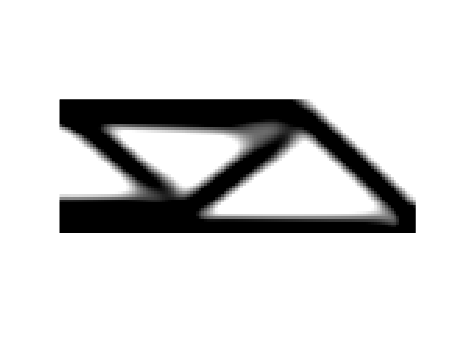

[rho0] = top(nelx,nely,volfrac,penal,rmin);

## Extending in 3rd (z-direction) to create a 3D example

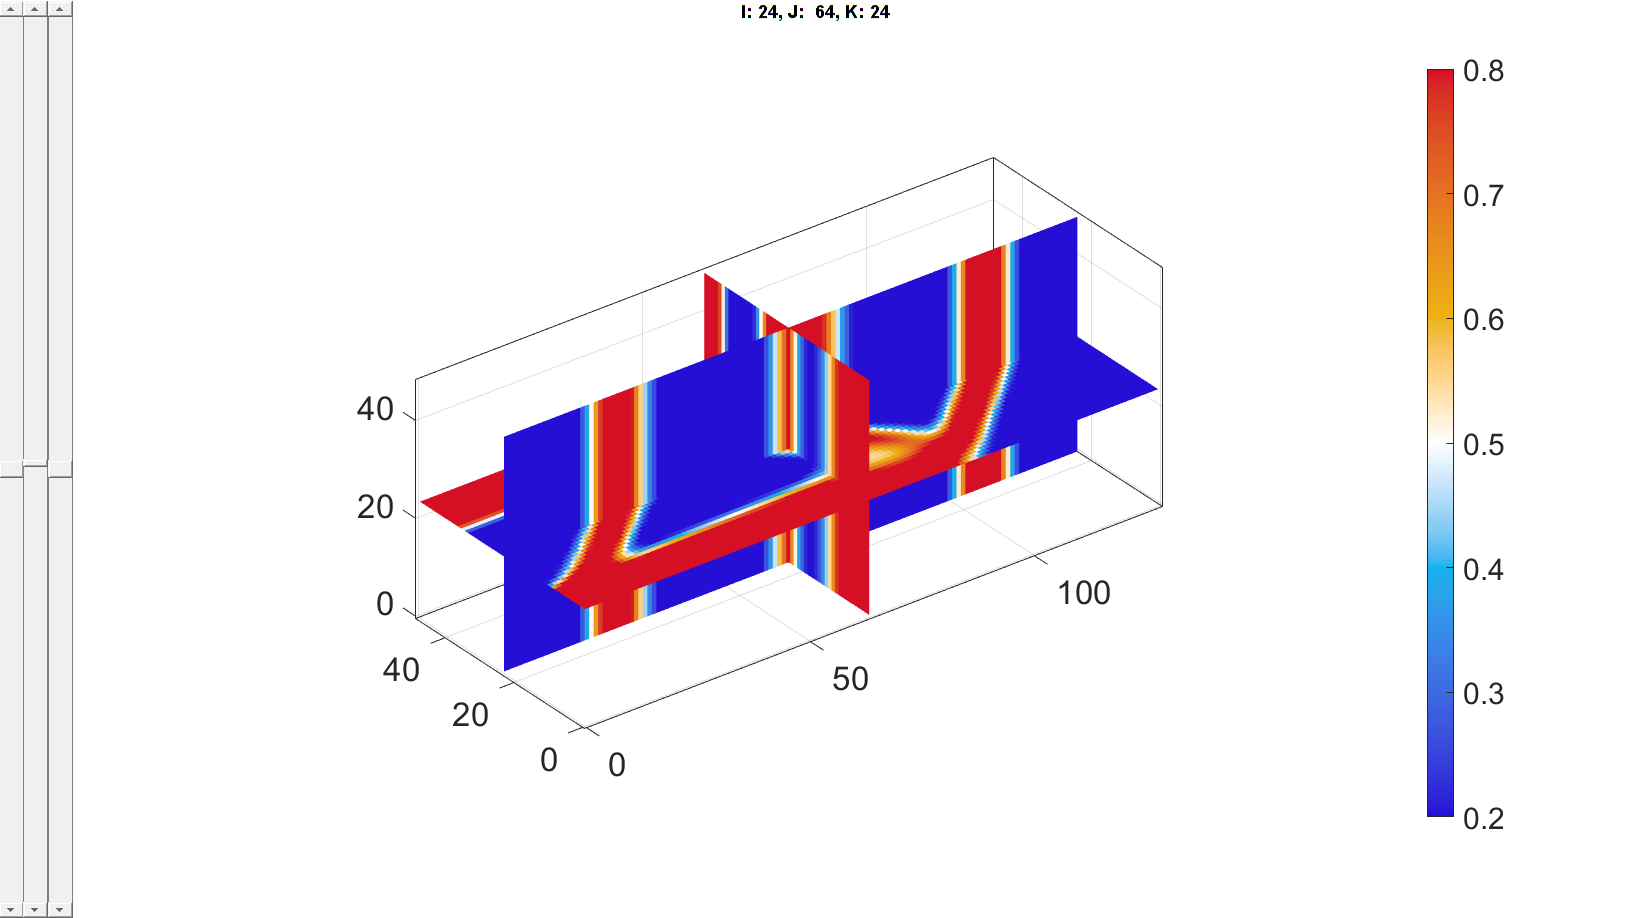

ext = [1, 1, nelz];
rho = repmat(rho0, ext); 

sv3(rho); colormap warmcold; % Visualize 3D field

## Access model elements and patch data

% Patch rho information to Elements and Faces
[E,V]=im2patch(rho,true(size(rho)),'h',v);
[F,rho_F] = element2patch(E,rho(:));

% Boundary faces
indBoundaryFaces = tesBoundary(F);
Fb = F(indBoundaryFaces,:);

% define face boundary rho values
if size(Fb,2)==4
    Fb = [Fb(:,[1 2 3]); Fb(:,[3 4 1]);]; % force to be triangles to be compatible with tet volume based in/out testing
    rho_Fb = [rho_F(indBoundaryFaces); rho_F(indBoundaryFaces)];
else
    rho_Fb = rho_F(indBoundaryFaces);
end

## Visualize 3D model and density data

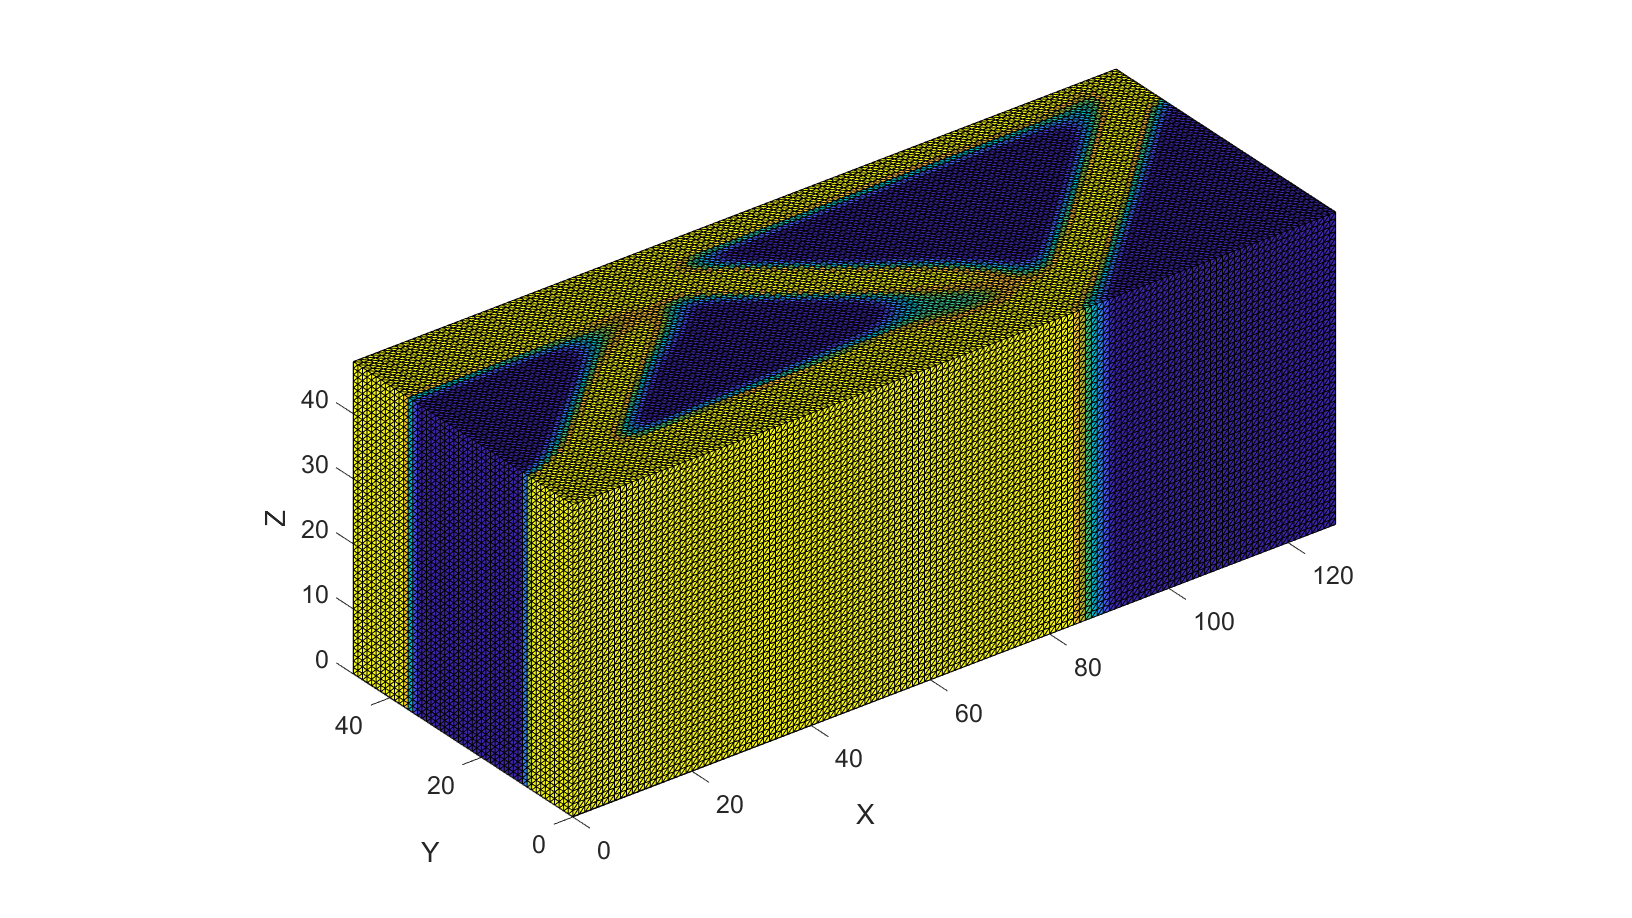

cFigure; 
gpatch(Fb,V,rho_Fb,'k');
axisGeom;

drawnow;

## Creating a grid grid with a desired spacing (e.g. as per desired spatial frequency)

spatialWaveLength = 6.66; % Nominal spatial wave length
samplingRate = 8; % Rate per "wave" 
voxelSize = spatialWaveLength/samplingRate;

## Interpolating model data onto grid with a desired spacing (e.g. as per desired spatial frequency)

[rho_VG,X,Y,Z,DG_im, imOrigin]= toGrid (E,Fb,V,rho,voxelSize);

## Visualize interpolated density on the grid

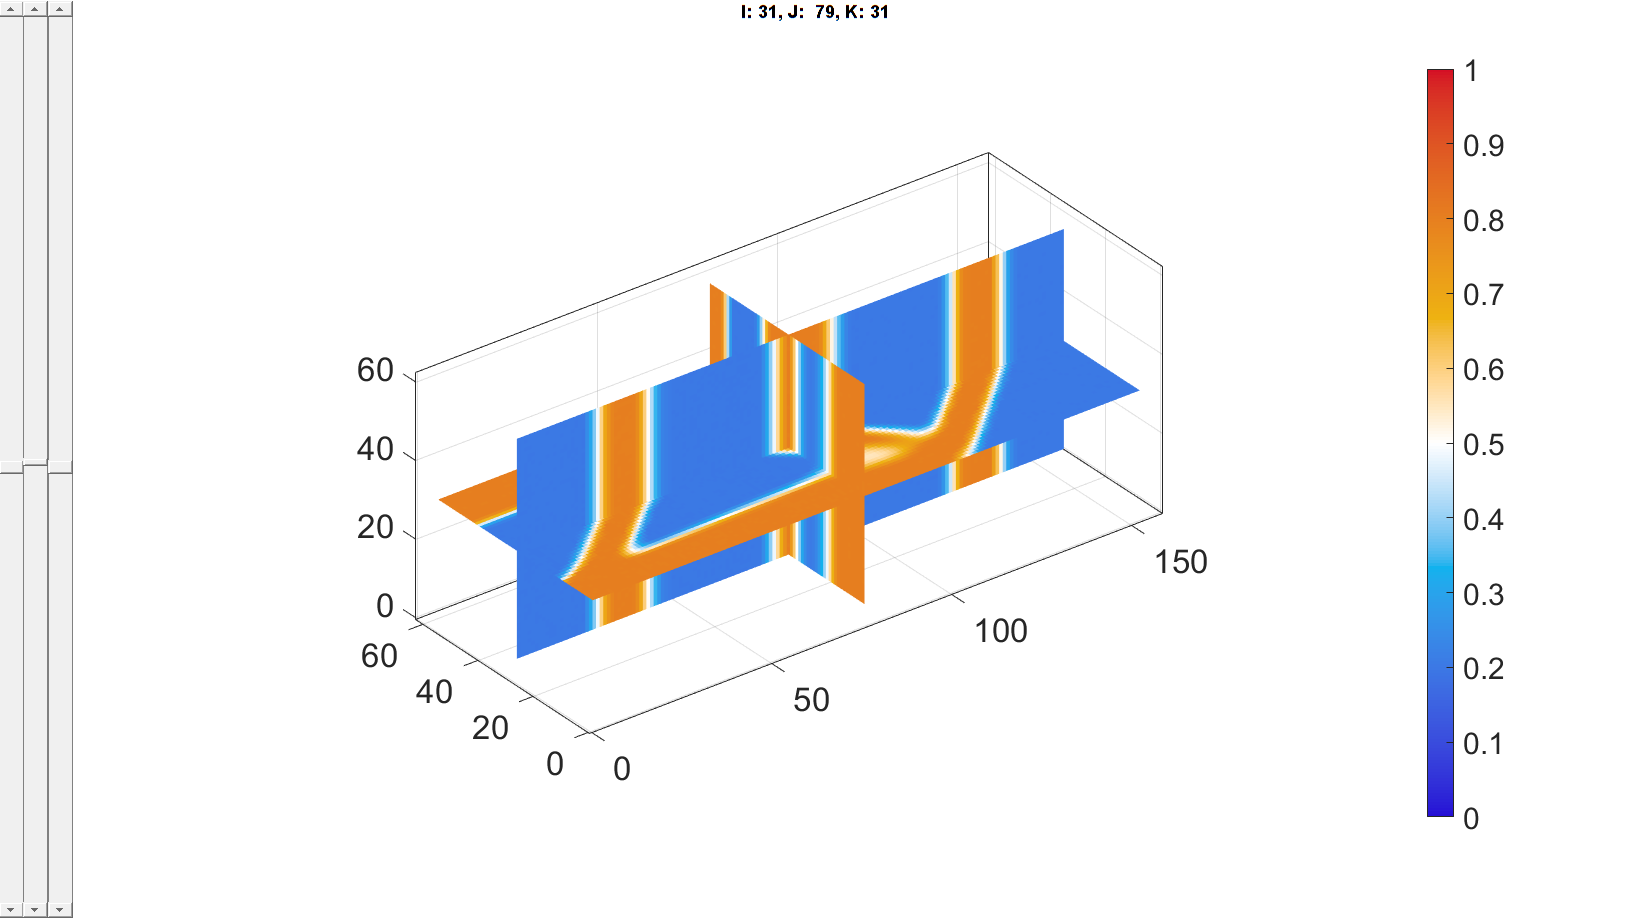

sv3(rho_VG); colormap warmcold;
caxis([0,1]);

## Mapping the density field to the equivalent gyroid levelSet field

l=(rho_VG-0.5)/-(1/3); 
k = (2*pi)/spatialWaveLength; % number of periods

## Visualizig levelSet data

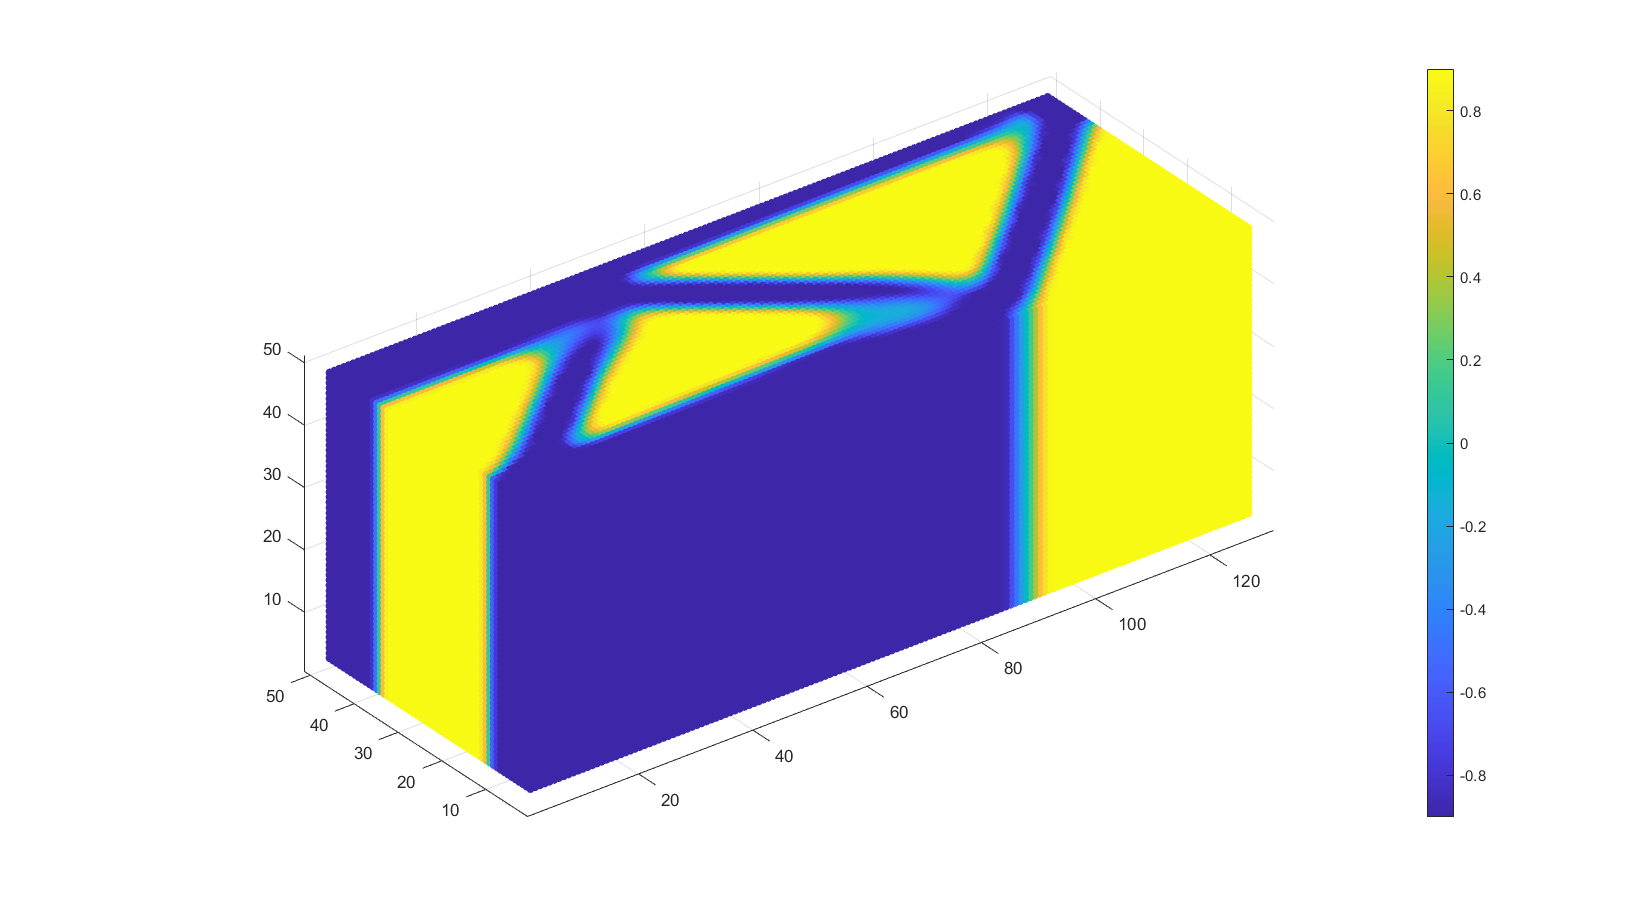

cFigure;  
scatter3(X(:),Y(:),Z(:),25,l(:),'filled');
axis tight; axis equal; 
colorbar;

## Evaluate triply periodic function

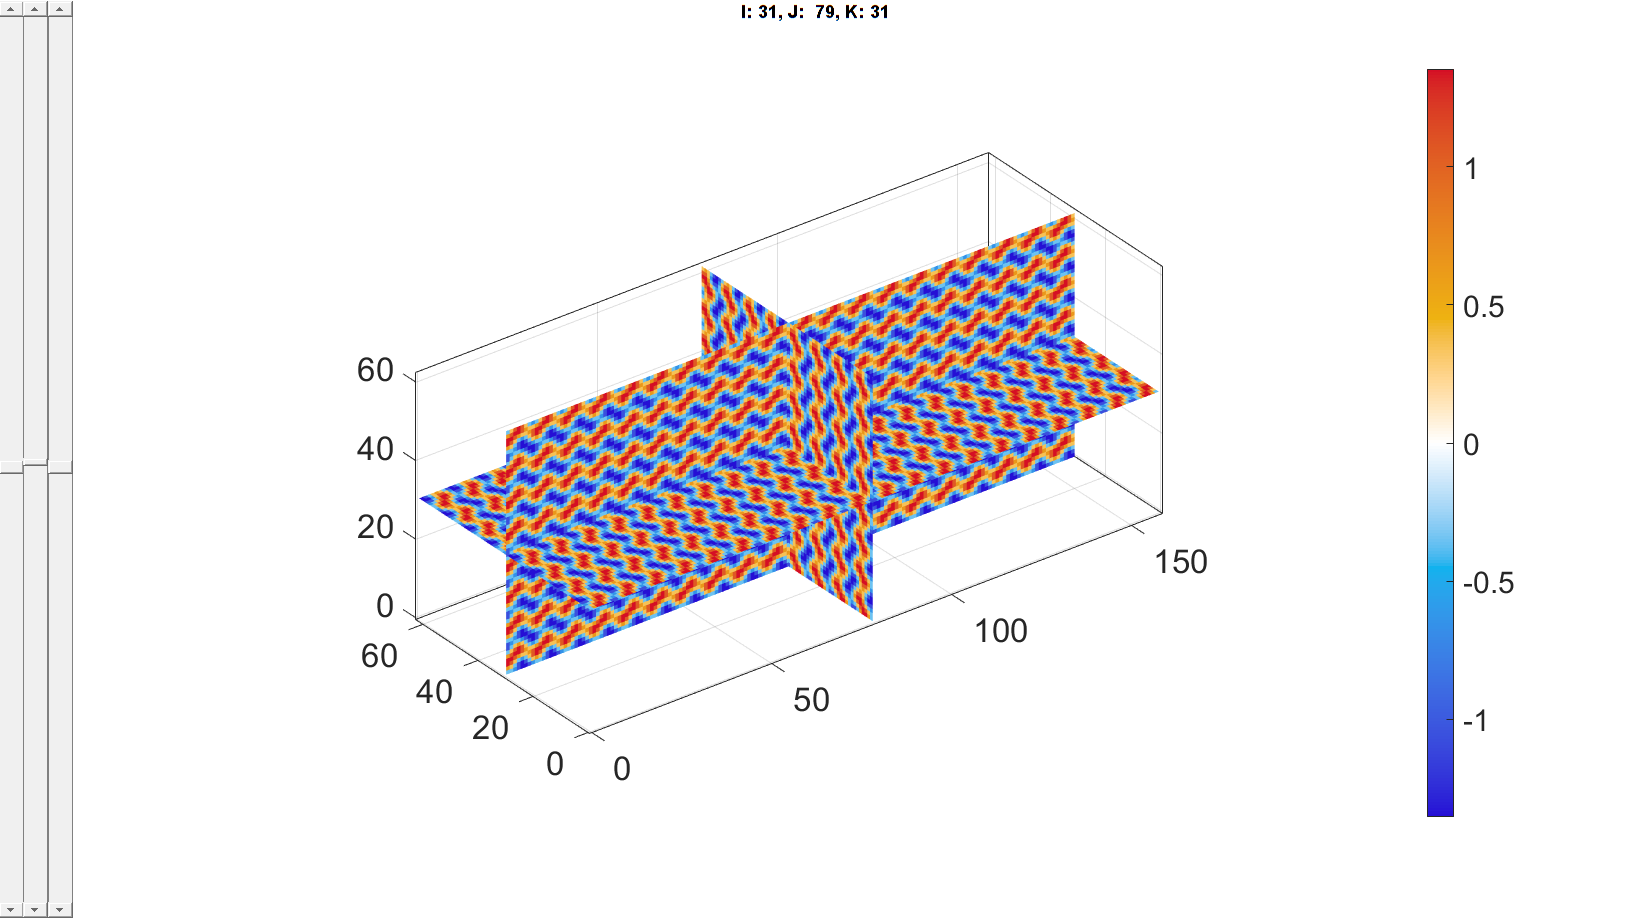

S=(sin(k.*X).*cos(k.*Y))+(sin(k.*Y).*cos(k.*Z))+(cos(k.*X).*sin(k.*Z)); 
sv3(S); colormap warmcold;

## Mapping the density field to the equivalent gyroid levelSet field

Gyroid "spans" -1.5-1.5, shift so minimum is at 1

i=2.5; % Leads to a minimum of 1 later
Sg=S+i; % S=-S-i;
l=l+i; % l=-l-i; % i:i+s
Sg=Sg./l; 

Sg=Sg-1; % bringing back to zero levelset
Sg=-Sg; % Negative

## Construct iso-surface

[Fg,Vg] = isosurface(X,Y,Z,Sg,0);

Vg=Vg+imOrigin; % shifting vertices

## Visualize surface gyroid function field

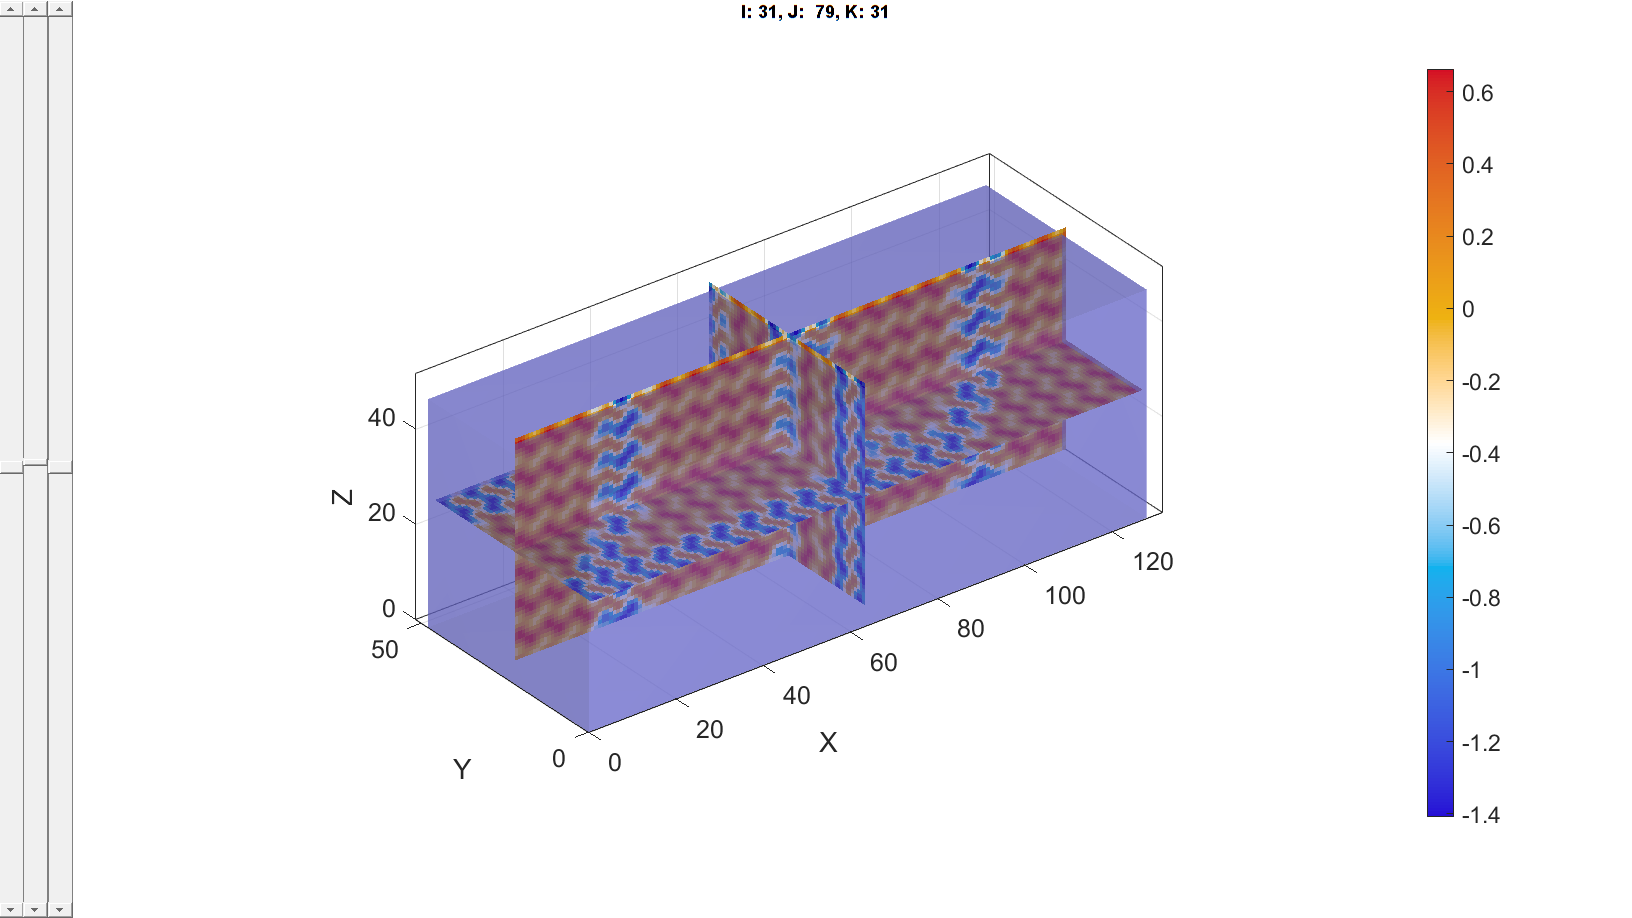

sv3(Sg, voxelSize); colormap warmcold;
hold on;
gpatch(Fb,V,'bw', 'none', 0.5);
axisGeom; 
% colormap spectral; icolorbar; 
camlight headlight; axis on;

drawnow;

## Visualization the distance image

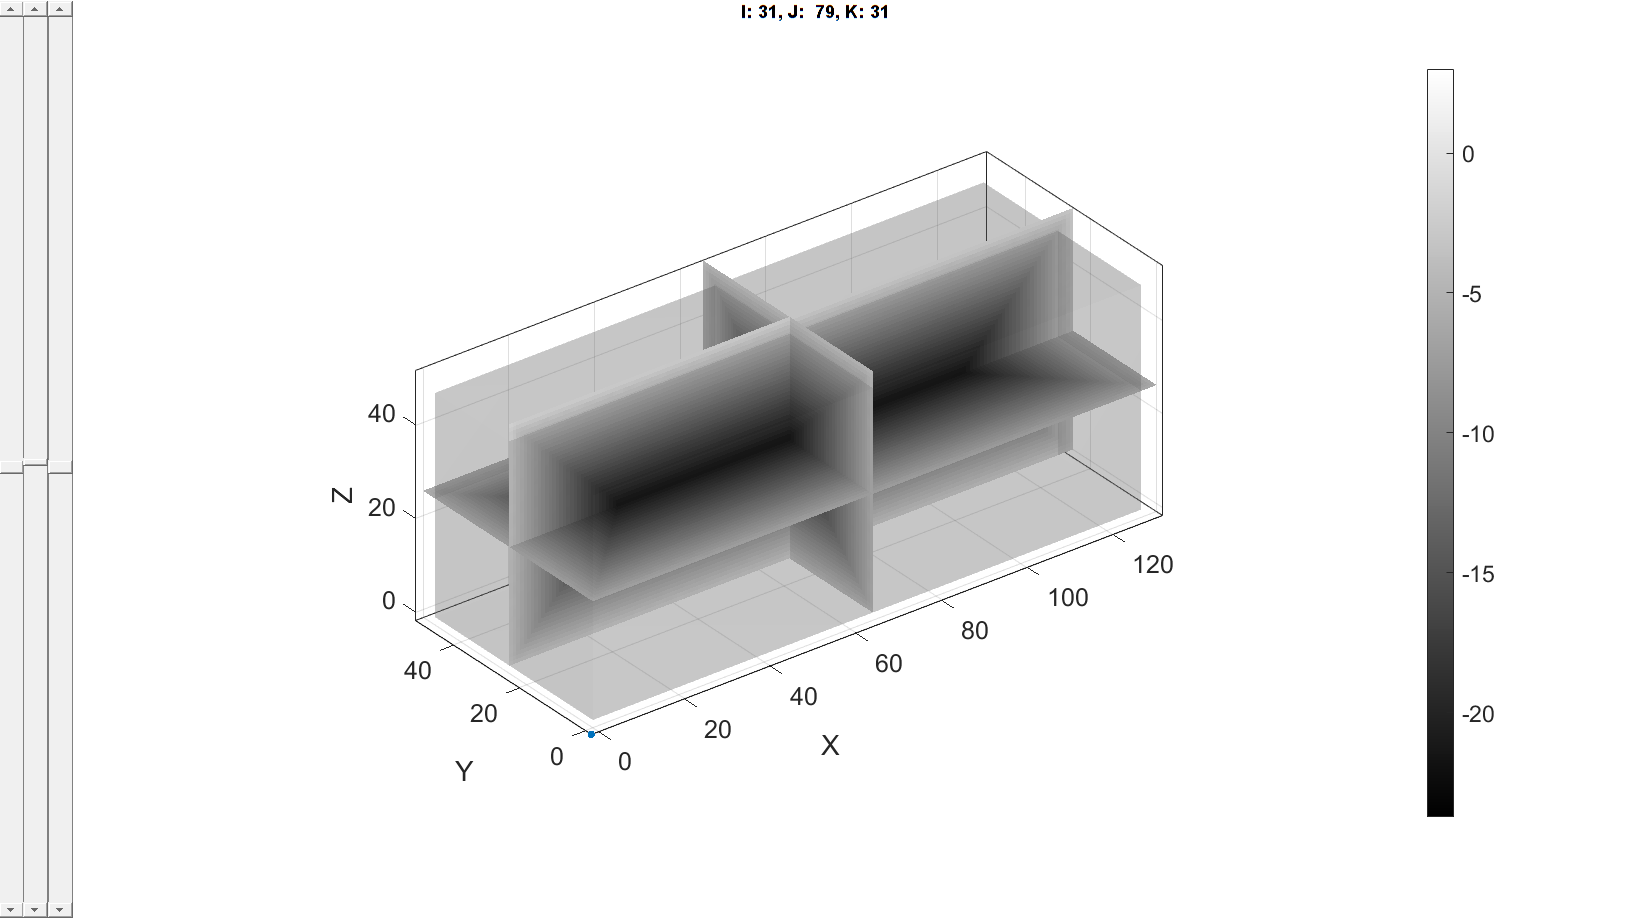

sv3(DG_im, voxelSize); hold on;

% Visualize boundary surface
gpatch(Fb,V,'kw','none',0.2);
scatterV(imOrigin, 20,'filled')
axisGeom; camlight headlight; axis on;

drawnow;

## create a shell boundary

R=DG_im; % a copy of the distance matrix
R(R<(-t/2))=-R(R<(-t/2))-t; % negate the distance field values at R=-t/2, and shift up

Ls=(DG_im)<=-t; % Filtering the region where mapped gyroid is needed

Sn=R; % R matrix for the whole image
Sn(Ls)=Sg(Ls); % keep mapped gyroid for R<=-t

## Visualize mapped field with thickness

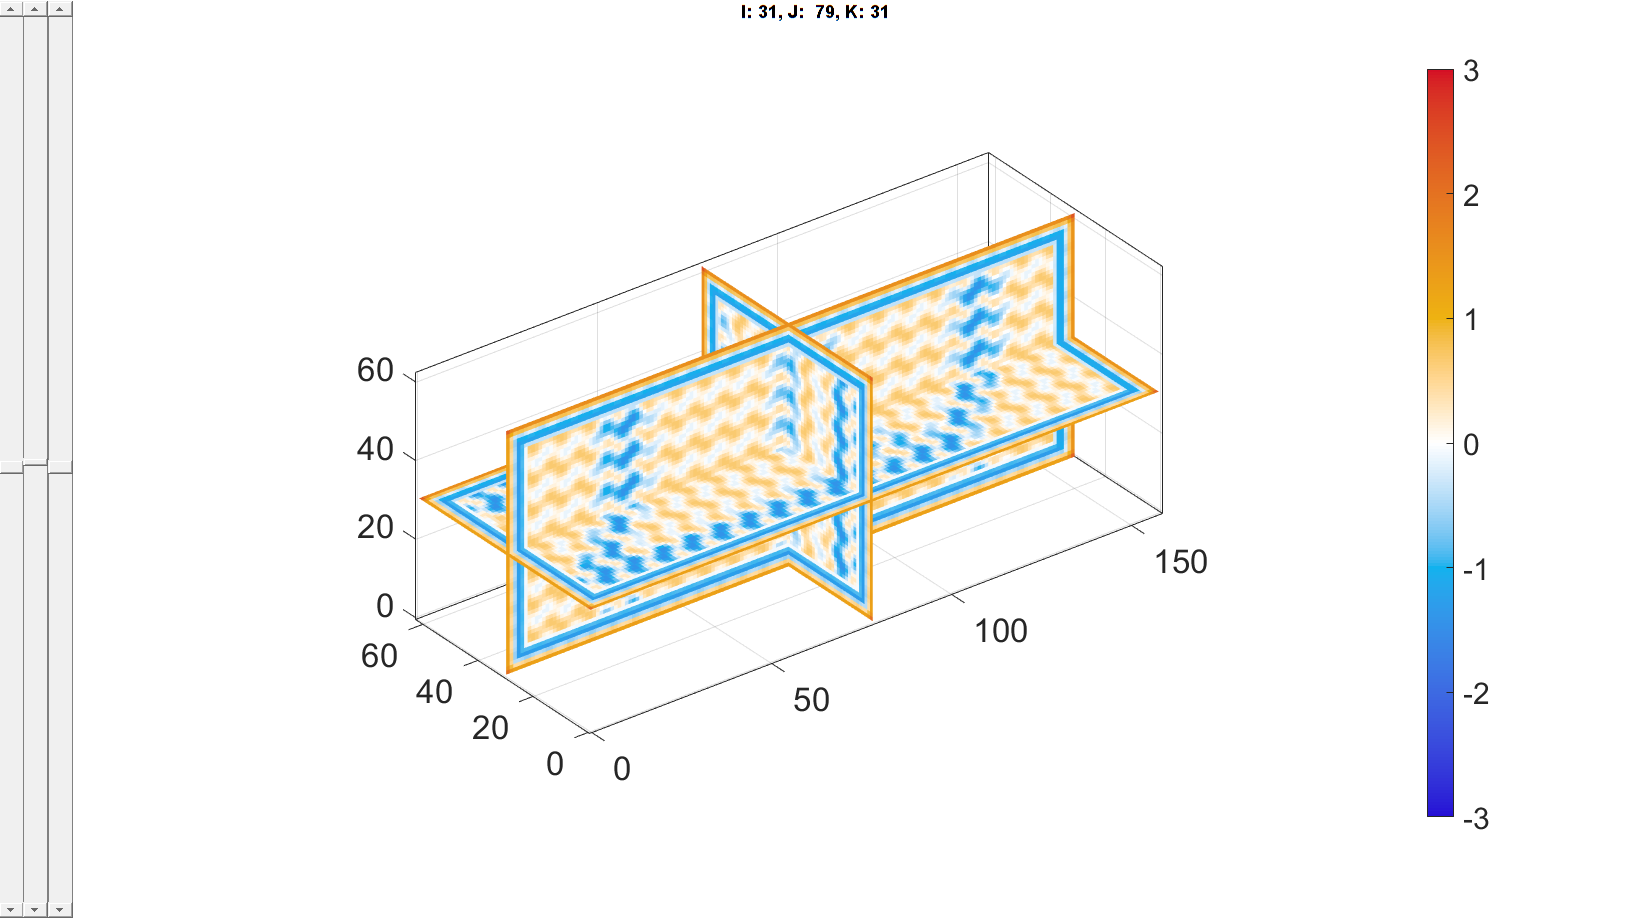

sv3(Sn); colormap warmcold
m=max(abs(Sn(:)));
caxis([-t, t])

## Construct iso-surface

[Fsn,Vsn] = isosurface(X,Y,Z,Sn,0); % create a gyroid isosurface 

Vsn=Vsn+imOrigin; % shifting vertices

## Visualize surface

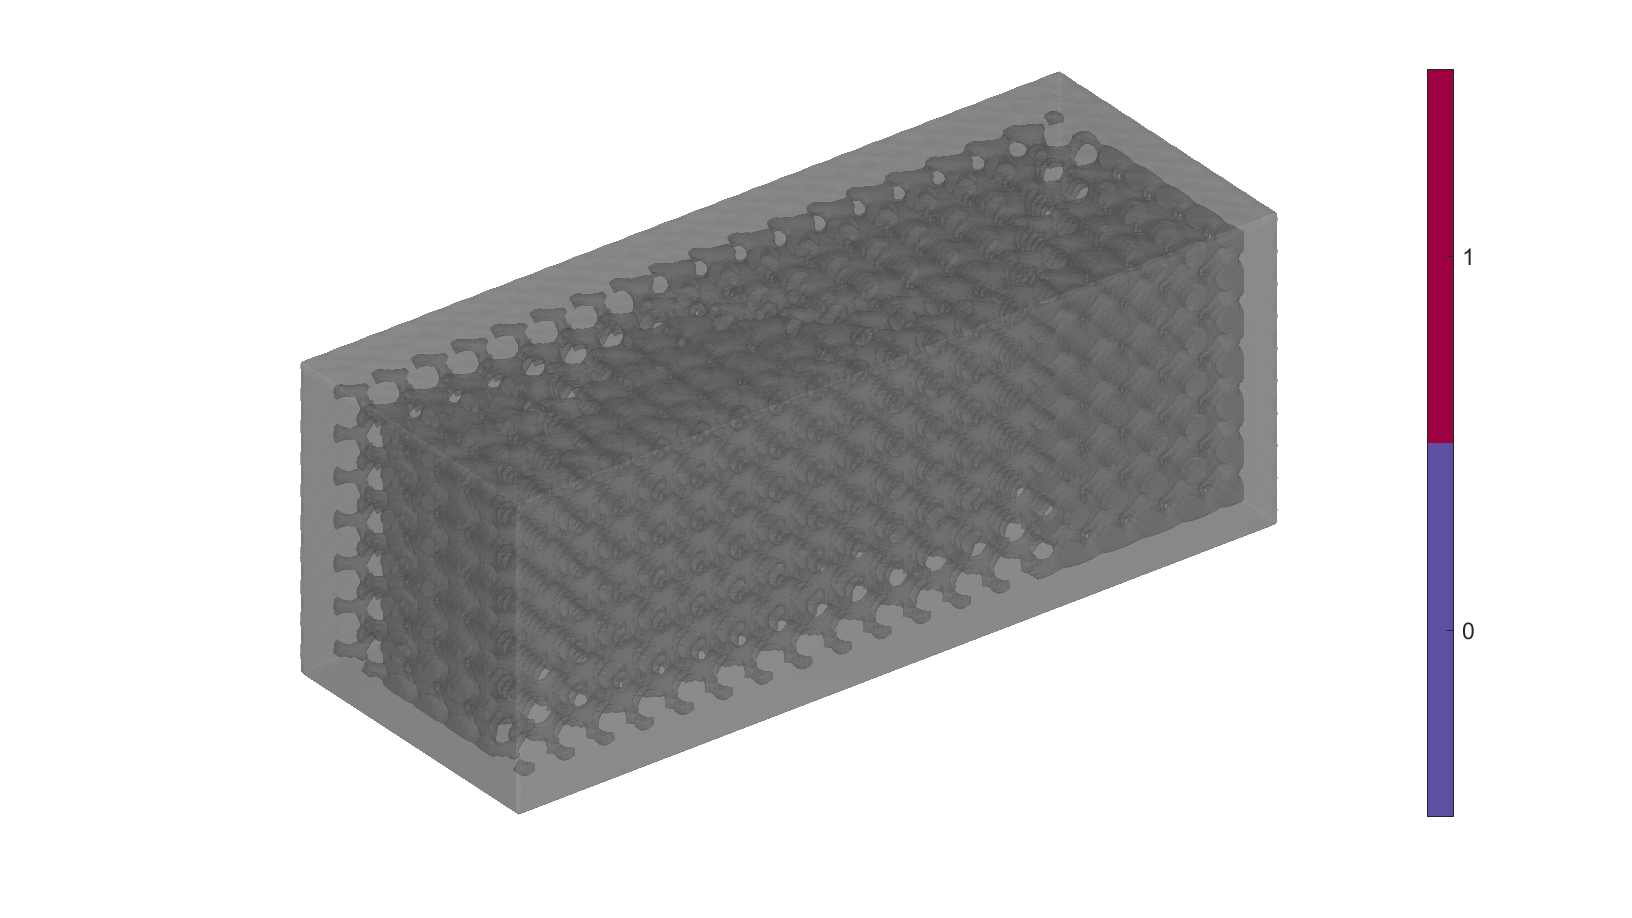

cFigure; 
gpatch(Fsn,Vsn,'kw','none',0.5);
axisGeom; colormap spectral; icolorbar; 
camlight headlight; axis off;

drawnow;

## Remove "Crumbs" and outer surface based on volume

% Using grouping to keep only largest group
groupOptStruct.outputType='label';
[G,~,groupSize]=tesgroup(Fsn,groupOptStruct); %Group connected faces

% Compute group volumes
numGroups=max(G);
volumeGroup = zeros(numGroups,1);
for q=1:1:numGroups
    logicCurrentGroup = G==q;
    Fsn_group = Fsn(logicCurrentGroup,:);
    volumeGroup(q) = patchVolume(Fsn_group,Vsn,1); 
end

volumeThreshold = 100; 

% Keeping only the gyroid porous surface
indGroupsKeep = find(volumeGroup>=volumeThreshold & volumeGroup==max(volumeGroup)); 
logicCrop = ismember(G,indGroupsKeep);
Fsn=Fsn(logicCrop,:); %Trim faces
G=G(logicCrop,:); %Trim faces group labels
volumeGroup=volumeGroup(indGroupsKeep); % Remaining volumes after crop

[Fsn,Vsn]=patchCleanUnused(Fsn,Vsn); %Remove unused nodes

## Visualize surface

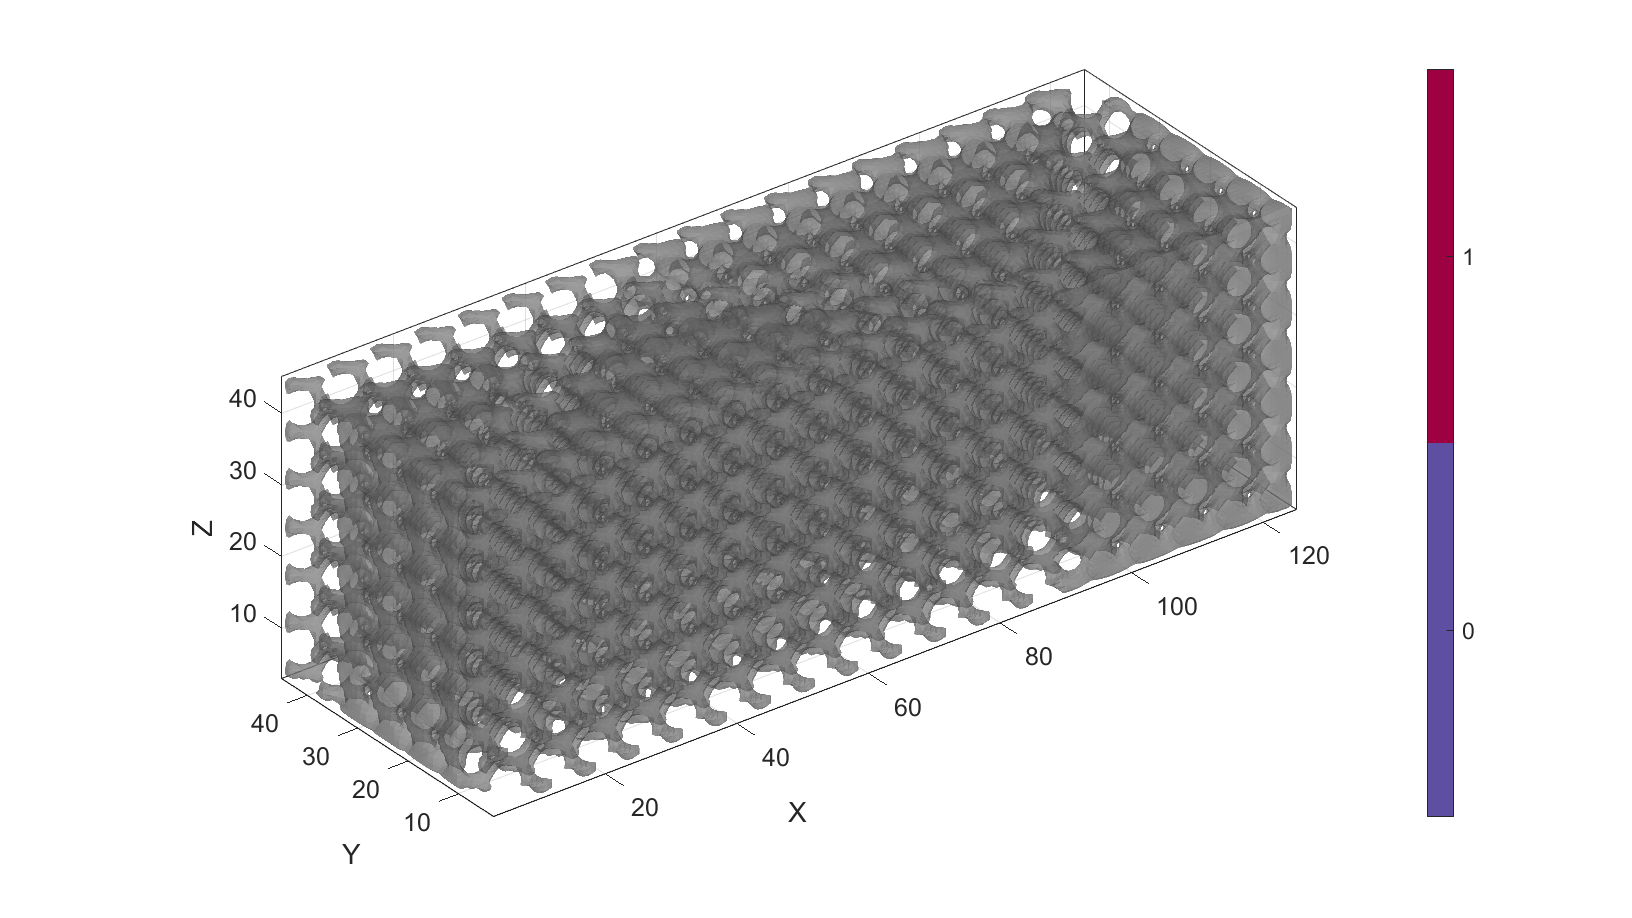

cFigure; hold on;
gpatch(Fsn,Vsn,'kw','none',0.5);
axisGeom; colormap spectral; icolorbar; 
camlight headlight; axis on;

drawnow;

## Merging the faces and vertices

[Fsn,Vsn]=mergeVertices(Fsn,Vsn); %Merge nodes
[Fsn,Vsn]=patchCleanUnused(Fsn,Vsn); %Remove unused nodes

## Visualize surface

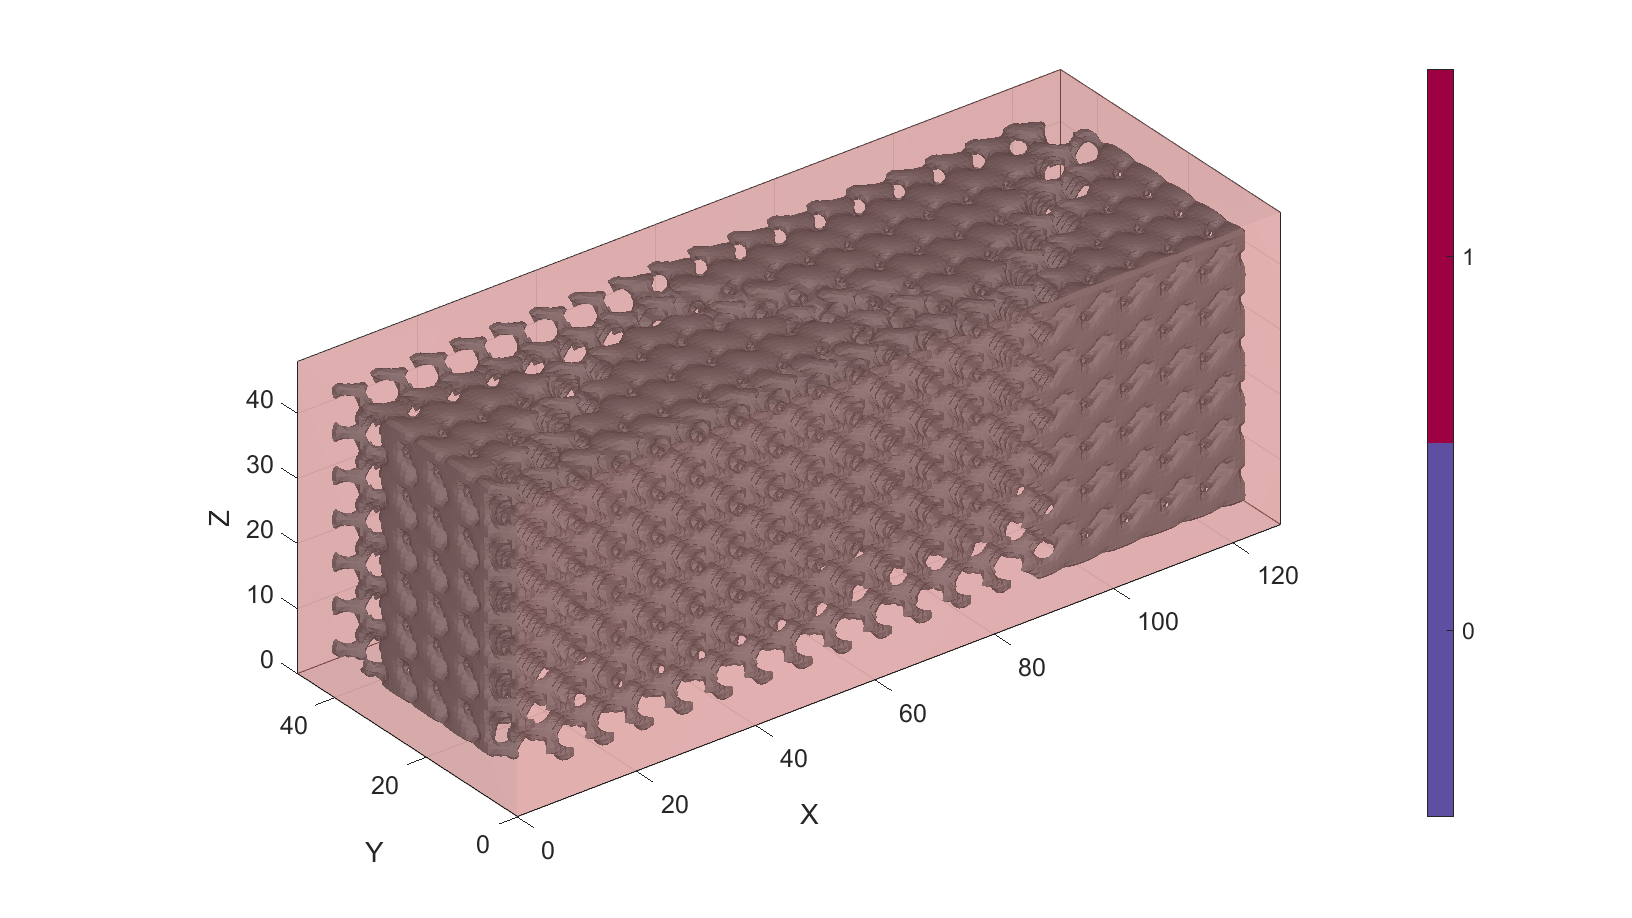

cFigure; hold on;
gpatch(Fsn,Vsn,'kw','none',1);
gpatch(Fb,V,'rw','none',0.3);

axisGeom; colormap spectral; icolorbar; 
camlight headlight; axis on;

drawnow;

## Join the two surfaces for STL version

[Fsn,Vsn,Csn]=joinElementSets({Fb,Fsn},{V,Vsn});
[Fsn,Vsn]=mergeVertices(Fsn,Vsn); %Merge nodes
[Fsn,Vsn]=patchCleanUnused(Fsn,Vsn); %Remove unused nodes

***LatticeWorks footer text*** 

License: [https://github.com/mahtab-vafaee/LatticeWorks/blob/main/LICENSE](https://github.com/mahtab-vafaee/LatticeWorks/blob/main/LICENSE)

Copyright (C) 2023 Mahtab Vafaeefar and the LatticeWorks contributors